# Worksheet 5, Part 2 / 4: Super-Spreading Events and COVID-19

*Author: *Zachary del Rosario, Fall 2022

*Important Note:* Worksheet 5 comes to you in **four**** parts**; `worksheet5_part1_assignment.mlx`, `worksheet5_part2_assignment.mlx`, and `worksheet5_part3_assignment.mlx`, and `worksheet5_part4_assignment.mlx`

*Learning Objectives:* As a result of working through this notebook, you will learn:

- How to read a scientific paper (building on your experience from the Phillips (1996) paper!)

- How the authors (Althouse et al.) use distributions to model different physical phenomena

- How to compare distributions in terms of their parameter values and shapes

- The difference between a *distribution *and a *sample*

- How to adjust a sample size to seek *rare events*

clear;

## Guided Reading of Althouse et al. (2020)

Download the Althouse et al. (2020) paper from the Readings folder on Canvas. (Hopefully you did this at the end of the last class!). We are going to read this paper over the rest of Worksheet 5.

*Brief, nerdy aside:* The phrase "et al." is short for "et alia," which is latin for "and others." So "Althouse et al." just means "Althouse and other co-authors."

Use the following exercise questions to guide your reading. Once you've finished all the reading questions (Exercises 1 through 4), the remaining questions will be self-contained within this part of the worksheet. (We'll return to reading in the next class.) Note that you can find the answers to all of the reading questions within the first three sections of the paper:

- Significance Statement

- Introduction

- Superspreading events, stochasticity, ...

When reading a scientific paper, it's helpful to keep in mind the "why?"—why did the authors write this paper? Understanding the "why" will help you make sense of the choices the authors made when deciding what evidence to present.

### Exercise 1 / 10 (Reading)

Answer the following questions: 

- What primary message are the authors trying to convey? 

-  *(Write your response here) *That in order to control the spread of Covid-19, it is important to understand and control routes of transmission.

- Why did they write this paper? 

-  *(Write your response here) *To address the knowledge gap and provide a better understanding of super spreading events (SSEs) in the transmission of Covid-19. They also want to provide recommendations for targeted interventions that focus on eliminating SSEs, therefore reducing large outbreaks.

- Thinking back to the Modeling Process reading from the beginning of the course: Is this modeling effort an example of *direct* or *indirect* action?

-  *(Write your response here) *This is an example of direct action because the modelers are giving ideas on how to eliminate SSEs with hopes that someone with the means to implement these strategies will.

- Thinking back to the Modeling Process reading from the beginning of the course: Is this modeling effort an example of *specific* or *general* modeling? What kind of modeling question are the authors trying to answer?

-  *(Write your response here) *It is specific because they authors are very specifically trying to answer the question of how SSEs affect Covid transmission and what can be done to get rid of them.

This paper is *very closely related* to the Jigsaw activity we did last class! Let's consider that for a moment.

### Exercise 2 / 10 (Reading)

Answer the following questions:

- The authors write, "As the virus has spread it has become clear that relying on a single value to characterize the number of secondary infections — and thus estimates of the transmissibility of this virus — is inadequate to capture the true transmission dynamics and subsequent risk to humanity." How does this relate to the Jigsaw activity we did last class?

-  *(Write your response here) *Last class we found that relying on the average as a single value estimate was inaccurate and led to many misconceptions and badly designed products. Similarly, a single value is not representitive of the transmissibility of the virus in this paper.

- The authors chose to model infection dynamics using random variables (probability theory). Why did they choose to do this, rather than model infection outcomes deterministically?

-  *(Write your response here) *The document emphasizes how the transmission of covid is stochastic, which means it involves random events and probabilities. The authors were better able to model this using random variables as opposed to deterministic ones.

Every scientific paper assumes that the reader is already familiar with some basic terms from the relevant scientific discipline. This makes reading the paper as a novice to the field *very challenging*. To successfully read a scientific paper, you'll have to get used to looking up definitions as you go along.

### Exercise 3 / 10 (Reading)

Answer the following questions about definitions. Note that all of the terms below are *mentioned* in the Althouse et al. (2020) paper, but you will not find definitions in the paper. You will have to practice finding definitions from another resource, e.g., the internet.

- What is $R_0$? (*Hint: *Try searching for "r naught" on the web.)

- *    (Write your response here) *It is known as the basic reproduction number, and it's an epidemiological metric used to measure the transmissibility of infectious diseases.

- What is a "secondary case"? How is this concept related to $R_0$? (Note that the paper uses the term "secondary infection," that is a confusing and misleading medical term. The term "secondary case" is from epidemiology, and is what $R_0$ actually refers to.)

- *    (Write your response here) *A secondary case is a person who gets a disease from exposure to a person with the disease. R naught is the expected number of secondary cases produced by a single infection in a completely susceptible population.

- What is a "super-spreading event"? How does it relate to $R_0$?

- *    (Write your response here) *A super spreader event is when one infected person infects an unusually high number of other people. In other words, there are a disproportionally large number of secondary cases relative to the standard reproduction rate, or r naught.

Now that we have some fundamental definitions under our belt, let's take a closer look at the specific modeling choices the authors made:

### Exercise 4 / 10 (Reading)

Answer the following questions:

- What physical phenomenon do the authors use a *poisson* distribution to represent?

-  *(Write your response here) *They use the distribution to represent the distribution of secondary infections in the context of the spread of a pathogen.

- What physical phenomenon do the authors use a *negative binomial* distribution to represent?

-  *(Write your response here) *They also use that to represent the distribution of secondary infections in the context of the spread of a pathogen.

- By modeling disease transmission with both poisson and negative binomial distributions, what comparison are the authors making?

-  *(Write your response here) *The authors are making a comparison between the transmission dynamics of an outbreak with a poisson-distributed secondary infection pattern and an outbreak with a negative binomial distributed secondary infection pattern. They compare the stochasticity and overdispersion of secondary infections in the two scenarios to understand the impact of superspreading events (SSEs) on the epidemic and also how the distribution of secondary infections affects the early dynamics and the likelihood of an outbreak growing large.

- Which distribution do the authors claim is *more appropriate* for modeling the transmission of SARS-CoV-2? How do they support that claim?

-  *(Write your response here) *They claim the negative binomial distribution is more accurate. They support this claim by saying that an outbreak with a negative binomial distribution of secondary infections with a small dispertion parameter has distinct transmission features that more accurately represent the transmission of the disease compared to a Poisson-distributed outbreak with the same r naught. 

Two distributions—the poisson distribution and negative binomial distribution—are *key* to understanding the Althouse et al. (2020) paper. The rest of the exercises in this part of the worksheet are designed to help you build understanding of these two distributions.

## Interpreting Probability

Probability is a measure of *relative frequency.* With a fair coin we expect to see heads and tails come up roughly equally often—so long as we flip the coin a large number of times. For instance, if we flip a fair coin 100 times, we would expect to see $\approx50$ heads ( $0.5 \times 100 = 50$ ).

However, for more complex situations with multiple possible outcomes—such as those modeled by the poisson and negative binomial distributions—it takes a bit more work to interpret the probabilistic properties of the situation.

First, let's look at two diferent "versions" of the same distribution. All distributions are *parameterized*, in the sense that they take numerical parameters that help determine their properties. The poisson distribution takes a single parameter $\lambda$. The next exercise will have you compare two poisson distributions with different values for $\lambda$.

### Exercise 5 / 10

Compute the mean of `pd1` and `pd3` (defined below). Answer the questions below.

% NOTE: Do not edit these distributions
pd1 = makedist('Poisson', 'lambda', 1);
pd3 = makedist('Poisson', 'lambda', 3);

% TODO: Compute the mean for both distributions
meanpd1 = mean(pd1)

meanpd1 = 1

meanpd3 = mean(pd3)

meanpd3 = 3

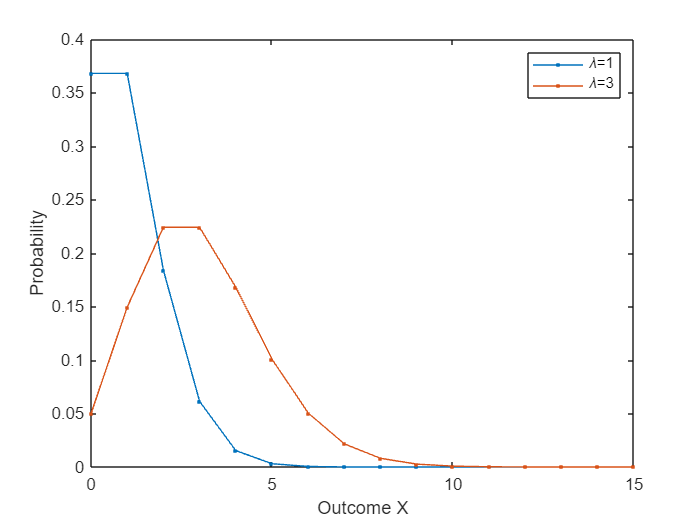

% NOTE: Do not edit this visualization; use this to answer the questions
% below
x = 0:15;
y1 = pdf(pd1, x);
y3 = pdf(pd3, x);

figure();
plot(x, y1, '.-', 'DisplayName', '\lambda=1'); hold on
plot(x, y3, '.-', 'DisplayName', '\lambda=3')
xlabel('Outcome X')
ylabel('Probability')
legend()

- How do the mean of `pd1` and `pd3` compare? Can you tell these two distributions apart using their mean?

-  *(Write your response here) *The mean of pd1 is a lot lower than that of pd3, you can tell these 2 distributions apart by this since pd1 is skewed much farther left than pd3.

- Compare the probabilities at higher values of the outcome $X$. Which distribution (Case 1 or Case 3) gives a higher probability for the outcome $X = 0$? 

-  *(Write your response here) *Case 1

- Which distribution gives a higher probability for larger values $X \geq 5$?

-  *(Write your response here) *Case 3

- Does either distribution give a nonzero probability to *extreme* events, say $X \geq 10$?

-  *(Write your response here) *No

Next, let's compare two distributions with different *shapes*.

### Exercise 6 / 10

Compute the mean of `pd_poisson` and `pd_negbin`. Answer the questions below.

% NOTE: Do not edit these distributions
pd_poisson = makedist('Poisson', 'lambda', 2);
pd_negbin  = makedist('NegativeBinomial', 'r', 0.1, 'p', 1 / (1 + 2 / 0.1));

% TODO: Compute the mean for both distributions
meanpoisson = mean(pd_poisson)

meanpoisson = 2

meannegbin = mean(pd_negbin)

meannegbin = 2

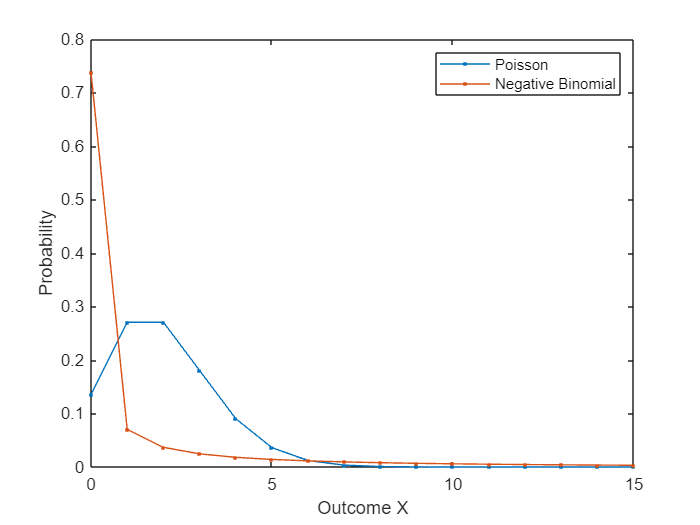

% NOTE: Do not edit this visualization; use this to answer the questions
% below
x = 0:15;
y_poisson = pdf(pd_poisson, x);
y_negbin  = pdf(pd_negbin, x);

figure();
plot(x, y_poisson, '.-', 'DisplayName', 'Poisson'); hold on
plot(x, y_negbin, '.-', 'DisplayName', 'Negative Binomial')
xlabel('Outcome X')
ylabel('Probability')
legend()

- How do the mean of `pd_poisson` and `pd_negbin` compare? 

-  *(Write your response here) *They are the same

- Can you tell these two distributions apart using their mean?

-  *(Write your response here) *No, because the negative binomial is skewed much farther to the left, but the means do not reflect this.

- Compare the probabilities at higher values of the outcome $X$. Which distribution (Poisson or Negative Binomial) gives a higher probability for values just slightly higher than the mean? 

-  *(Write your response here) *The poisson distribution.

- Which distribution gives a higher probability for values much higher than the mean?

-  *(Write your response here) *The poisson distribution.

- Does either distribution give a nonzero probability to *extreme* events, say $X \geq 10$?

-  *(Write your response here) *No

Notice that the probability values get *very* small for larger values of $X$. But are they *exactly *zero? If they're not *exactly* zero, then there is still a chance that if we realize a very large number of observations, we might see some of these huge X values.

To help visualize data that vary over a very large range—engineers often say "over multiple orders of magnitude"—we can use a log-plot. We can replace `plot()` with `semilogy()` to produce a plot that uses a log scale on its y axis.

### Exercise 7 / 10

Edit the code below to create a semilogy() plot. Answer the questions below.

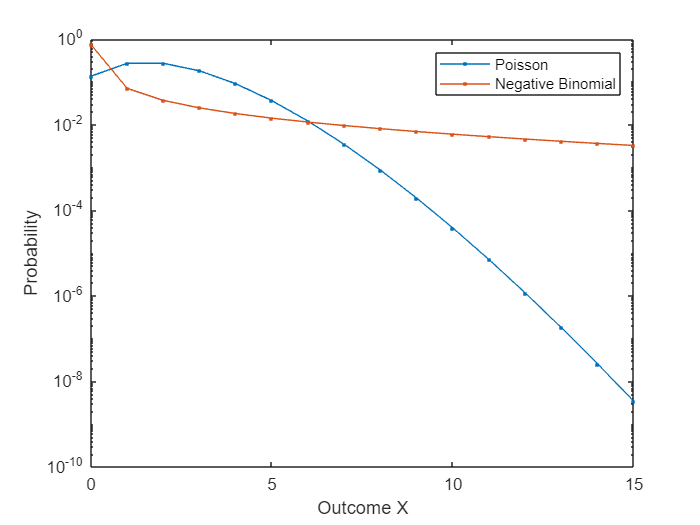

% TODO: Edit the code below to create a semilogy() plot
figure();

semilogy(x, y_poisson, '.-', 'DisplayName', 'Poisson'); hold on
semilogy(x, y_negbin, '.-', 'DisplayName', 'Negative Binomial')

xlabel('Outcome X')
ylabel('Probability')
legend()

- Does either distribution give a nonzero probability to *extreme* events, say $X \geq 10$? 

-  *(Write your response here) *No

- Did you come to a different conclusion from when you answered this question above?

-  *(Write your response here) *Yes because now it is more obvious that it is just a very small decimal percentage.

- Imagine we drew 1000 realizations from the `pd_negbin` distribution. Would you expect to see any outcomes with $X \geq 10$? Why or why not?

-  *(Write your response here) *Maybe a few since the probability is over 1/1000.

- Althouse et al. claim that a negative binomial distribution is a better model for super-spreading events, as compared with a poisson distribution. Based on this plot, why is a negatvie binomial distribution the better model for SSEs?

-  *(Write your response here) *There is less variability in the probability of certain outcomes over 10, this takes into account SSEs.

- The negative binomial distribution is said to have a "longer right tail" than the poisson distribution. Based on this plot, why do you think this is?

-  *(Write your response here) *The negative binomial distribution has a much smaller slope than the poisson distribution, so it will have a probability above 0 for many more outcomes.

## Working with Parameterizations

Althouse et al. (2020) uses the negative binomial distribution to model the number of secondary cases resulting from an index case. However, they parameterize the negative binomial in terms of the basic reproductive number $R_0$ and a *dispersion parameter* $k$. How do we use these numbers in Matlab, which asks for $r$ and $p$ parameters?

I had to figure out how to relate $R_0, k$ with $r, p$ by reading a whole bunch of papers. I'll spare you the literature search and walk you through the mathematics.

First, it turns out that the *dispersion parameter* $k$ is just another name for the $r$ parameter required by Matlab. Thus $k = r$—simple so far!

The basic reproductive number $R_0$ is the *mean *number of secondary cases resulting from an initial infection. The mean $\mu$ of a negative binomial distribution is given by


$$\mu = \frac{(1 - p) r}{p}$$


Using the information above, you (yes you!) can determine how to set the $p$ parameter.

### Exercise 8 / 10

Use algebra to determine the correct values for $r, p$ based on the given values for $R_0, k$.

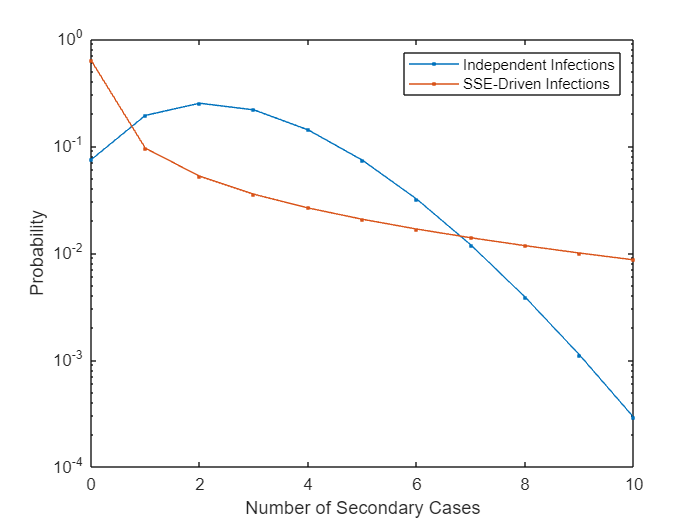

% NOTE: Do not edit these parameter values; use this to parameterize the
% negative binomial distribution
R0 = 2.6;
k = 0.16;

% TODO: Determine r and p for the negative binomial distribution based on
% R0 and k
r = k;
p = r/(R0+r);

% NOTE: Do not edit the code below; use this to check your work
pd_indep = makedist('Poisson', 'lambda', R0);
pd_sse = makedist('NegativeBinomial', 'r', r, 'p', p);

assert(abs(mean(pd_sse) - 2.6) < 1e-3, 'The mean of your distribution is incorrect')
assert(abs(var(pd_sse) - 44.85) < 1e-3, 'The variance of your distribution is incorrect')

% Visualize
x = 0:10;
y_indep = pdf(pd_indep, x);
y_sse = pdf(pd_sse, x);

figure();
semilogy(x, y_indep, '.-', 'DisplayName', 'Independent Infections'); hold on;
semilogy(x, y_sse, '.-', 'DisplayName', 'SSE-Driven Infections')
xlabel('Number of Secondary Cases')
ylabel('Probability')
legend()

### Distribution vs Sample

Now that we've learned how to set up distributions the same way Althouse et al. do, we need to interpret what realizations from these distributions *mean*. Imagine we flipped a fair coin 10 times; would you expect to see *exactly* five heads? We don't need to guess; let's try simulating coin flips!

% The following code will simulate the outcome of 10 coin flips four times.
% Let's let Heads == 1 and Tails == 0. Do you see *exactly* five coins
% Heads-up in each of the four columns?
(rand(10, 4) >= 0.5)

ans = 10×4 logical array
   1   1   0   1
   1   0   0   0
   0   1   1   0
   1   0   0   1
   1   1   1   1
   0   1   0   1
   0   1   1   1
   0   1   0   0
   1   1   0   1
   0   0   0   1


As you can see, we do *not* see exactly five heads each time. This is part of the difference between a random *sample* (a small collection of values) and a full distribution (which represents an *infinite *number of realizations).

We will see the same "mismatch" if we draw a sample from a distribution and compare the two. The following code draws a sample of 100 realizations from a poisson distribution.

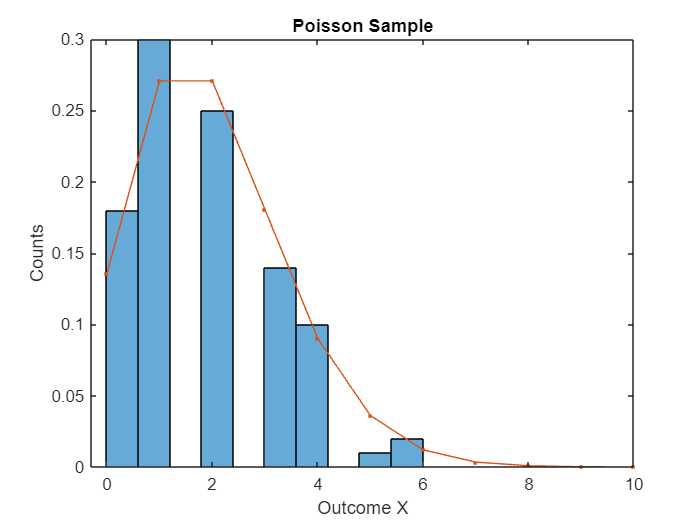

% Draw a sample of 100
X_poisson = random(pd_poisson, 1, 100);

% Visualize
x = 0:10;
y_poisson = pdf(pd_poisson, x);
figure();
histogram(X_poisson, 'NumBins', 10, 'Normalization', 'probability'); hold on
plot(x, y_poisson, '.-')
xlabel('Outcome X')
ylabel('Counts')
title('Poisson Sample')

**This is variability in action.** In a sense, variability adds uncertainty to any system "twice":

- Variability means outcomes are inherently uncertain.

- Since we will only ever see a finite number of realizations, we have *additional* uncertainty from our limited (finite) sample.

You'll work with this idea more in the next exercise:

### Exercise 9 / 10

Draw a sample with at least 1000 realizations. Answer the questions below.

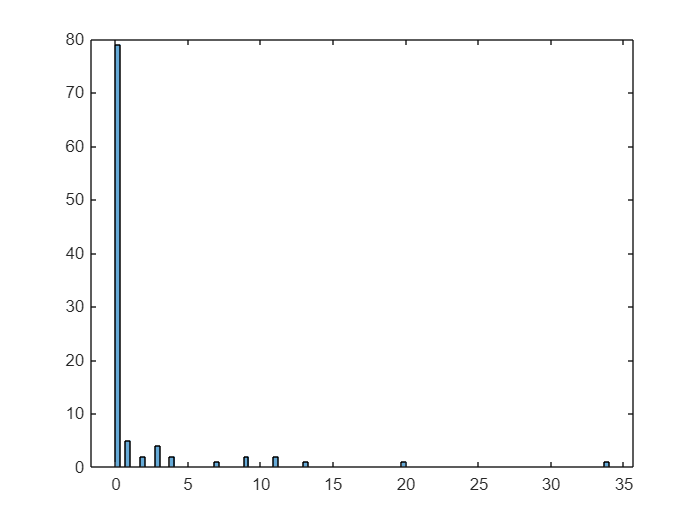

X_negbin = random(pd_negbin, 1, 100);
figure();
histogram(X_negbin, 'NumBins', 100);

- Did you observe any values with $X \geq 10$? 

- *    (Write your response here) *Yes

- Did this agree with your answer to Exercise 6 above?

- *    (Write your response here) *No

## Sampling for Rare Events

An event with a small probability is called a *rare event*. A practical consequence of small probabilities is that we will need to gather a large sample (many realizations) in order to observe rare events. If we happen to know the probability of the event we are trying to observe—or if we at least have an *estimate* for the probability—we can use that to help plan our data collection. Namely, we can plan our *sample size*—how many realizations we plan to gather—based on our (estimated) probability.

Let's imagine we wanted to observe *just one* event that occurs with a small probability $p$. We would draw a sample of size $n_{\text{samp}} = 1 / p$. Of course, we would still be extremely unlikely to observe that event from a sample of that size! 

It would be a better idea to pick a reasonable *target number* of events to observe $n_{\text{target}}$; we would then draw a sample of size $n_{\text{samp}} = n_{\text{target}} / p$. We can use this "rule of thumb" to help set a sample size that is likely to produce rare events.

### Exercise 10 / 10

Choose a target number of times you want to see the rare event $X = 20$. Determine a sample size $n_{\text{samp}}$ that is likely to give you that target number of counts, and draw a sample of that size. Answer the questions below.

% TODO: Evalute the probability that X == 20 for pd_negbin
pr20 = X_negbin(:,20)/100;
% TODO: Use pr20 to determine a sample size that is likely to give you a
% rare event
n_target = 3;
n_samp = 300;

% TODO: Draw a sample from pd_negbin with the sample size you determined
X_rare = random(pd_negbin, 1, 300);

% NOTE: Do not edit this code; use this to check your work
n_target

n_target = 3

count_20 = sum(X_rare == 20)

count_20 = 3


assert(count_20 > 0, 'Your sample did not contain any rare events; try adjusting your sample size.')

- Did `count_20` come out to be *exactly equal *to your target value? 

-  *(Write your response here) *No

- Why or why not?

-  *(Write your response here) *My sample size most likely was not large enough, I should have taken into account the possibility that the rare event would not happen.

## Looking Forward

This part of the worksheet was all about understanding distributions and using them to model a key component of disease transmission—the number of secondary cases. Next time we'll use this understanding in a new kind of model for disease transmission—a *branching process *model.